fs = 44100;
T0 = 2

T0 = 2

t_vec = 1/fs:1/fs:T0

t_vec =     0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011


test_vec = sin(500*2*pi*t_vec) +0.5*sin(2000*2*pi*t_vec) + 0.25*sin(5000*2*pi*t_vec)

test_vec =     0.3751    0.6591    0.8003    0.8074    0.7414    0.6833    0.6934    0.7812    0.9028    0.9839    0.9594    0.8094    0.5733    0.3348    0.1856    0.1844    0.3302    0.5649    0.8007    0.9621    1.0199    1.0018    0.9748    1.0082    1.1349    1.3315    1.5259    1.6301    1.5815    1.3732    1.0591    0.7297    0.4719    0.3311    0.2936    0.2981    0.2700    0.1614   -0.0232   -0.2269   -0.3683   -0.3819   -0.2523   -0.0249    0.2123    0.3669    0.3826    0.2627    0.0649   -0.1293


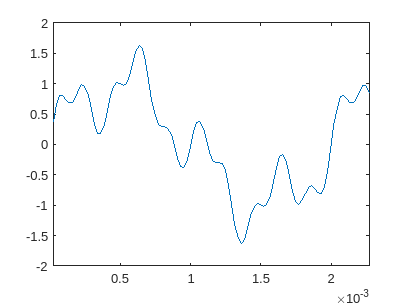


plot(t_vec, test_vec)
xlim([1/fs 100/fs])


[test_vec, fs] = audioread("scrambled_eggs_5s.wav")

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 160)
    [y, Fs] = readaudio (filename, range, datatype);

sound(test_vec, fs)

## Place poles/zeros

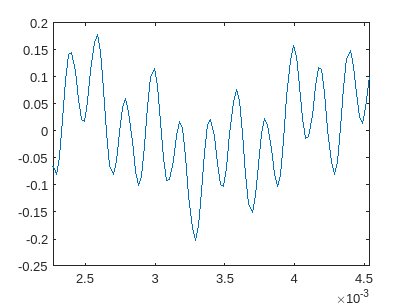

% Poles/zeros are assigned in this: 
pos_z = [0.7*exp(1j*pi/100) 0.7*exp(-1j*pi/100)];
pos_p = [0.7*exp(1j*pi/2) 0.7*exp(-1j*pi/2)];

% Converted to A's and B's:
B = poly(pos_z);
A = poly(pos_p);

filt1 = filter(B,A, test_vec);
plot(t_vec, filt1)
xlim([100/fs 200/fs])

## Graphical Equalizer

% As speech signals are logaritmic-ish in nature, the bands are not made
% equally big, but increases with a multiplier of 1.73x starting from 0:50
mult = 1.73;
coeffs = [1,0.9,0.8,0.75,0.7,0.65,0.65,0.7,0.75,0.8,0.9,1]

coeffs =     1.0000    0.9000    0.8000    0.7500    0.7000    0.6500    0.6500    0.7000    0.7500    0.8000    0.9000    1.0000



cut = [];
for i = 0:10
    cut = [cut 50/fs*2*mult^i];
end
cut = [cut 0.999]

cut =     0.0023    0.0039    0.0068    0.0117    0.0203    0.0351    0.0608    0.1052    0.1819    0.3148    0.5445    0.9990


ans = 0.9990

f_vec =     0.0023    0.0039    0.0068    0.0117    0.0203    0.0351    0.0608    0.1052    0.1819    0.3148    0.5445    0.9990


H_vec =      0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0


i = 1

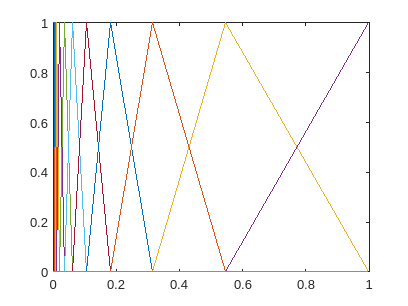

max_ord = 50

b =     0.0063    0.0169    0.0103   -0.0211   -0.0301    0.0300    0.0894    0.0179   -0.1345   -0.1133    0.1407    0.2615   -0.0416   -0.3868   -0.1649    0.4219    0.4555   -0.2643   -0.6905   -0.0520    0.7699    0.4640   -0.6154   -0.8199    0.1590    1.7965    0.1590   -0.8199   -0.6154    0.4640    0.7699   -0.0520   -0.6905   -0.2643    0.4555    0.4219   -0.1649   -0.3868   -0.0416    0.2615    0.1407   -0.1133   -0.1345    0.0179    0.0894    0.0300   -0.0301   -0.0211    0.0103    0.0169


f_vec =     0.0023    0.0039    0.0068    0.0117    0.0203    0.0351    0.0608    0.1052    0.1819    0.3148    0.5445    0.9990


coeffs =     1.0000    0.9000    0.8000    0.7500    0.7000    0.6500    0.6500    0.7000    0.7500    0.8000    0.9000    1.0000


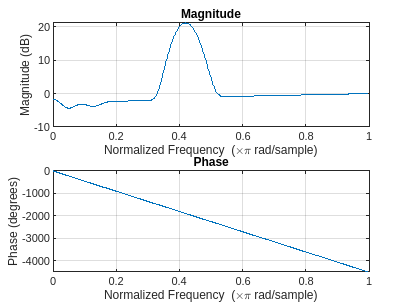

cut(end)

## FIR solution:

coeffs

coeffs =     1.0000    0.9000    0.8000    0.7500    0.7000    0.6500    0.6500    0.7000    0.7500    0.8000    0.9000    1.0000


max_order = 5000

max_order = 5000

cut

cut =     0.0023    0.0039    0.0068    0.0117    0.0203    0.0351    0.0608    0.1052    0.1819    0.3148    0.5445    0.9990



b = zeros(max_order +1, 12);
b(:, 1) = fir1(max_order, cut(1), 'low');
for i = 2:11
    b(:, i) = fir1(max_order, [cut(i-1) cut(i)], blackman(max_order + 1), 'bandpass');
end
b(:, 12) = fir1(max_order, cut(11), 'high');
b_scaled = b.*coeffs;
b_joined = zeros(max_order + 1,1);

for i = 1:12
    b_joined = b_joined + b_scaled(:,i);
end
b_joined

b_joined =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


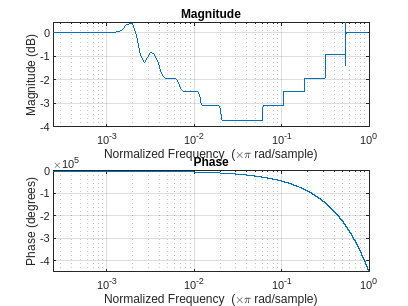

freqz(b_joined, 1, 4096)
ax = findall(gcf, 'Type', 'axes');
set(ax, 'XScale', 'log');

ans = 2698

btest = 1.0e-04 *

    0.0674         0   -0.1347         0    0.0674


atest =     1.0000   -3.9925    5.9776   -3.9778    0.9927


ans = 0.0023

ans = 0.0039

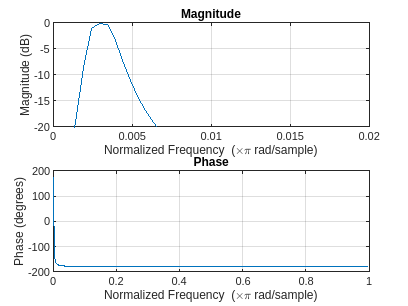

a =      0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0


coeffs =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9000    0.8000    1.0000    0.9000    0.8000


a_j = 1.0e+10 *

    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0002
   -0.0010
    0.0040
   -0.0132


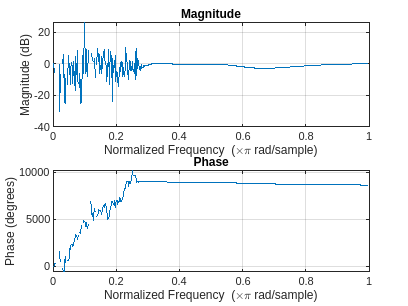

imp =    -0.0792
   -0.1153
   -0.0929
   -0.0229
    0.0279
   -0.0630
   -0.0312
   -0.0330
   -0.0022
    0.0218


i = 1

inter =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


i = 2

inter =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0002


i = 3

inter =    -0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0003
   -0.0003
   -0.0004
   -0.0005
   -0.0006


i = 4

inter =    -0.0000
   -0.0001
   -0.0002
   -0.0004
   -0.0005
   -0.0007
   -0.0009
   -0.0011
   -0.0013
   -0.0015


i = 5

inter =    -0.0000
   -0.0002
   -0.0005
   -0.0010
   -0.0014
   -0.0018
   -0.0023
   -0.0027
   -0.0032
   -0.0036


i = 6

inter =    -0.0001
   -0.0005
   -0.0013
   -0.0025
   -0.0035
   -0.0044
   -0.0052
   -0.0060
   -0.0067
   -0.0072


i = 7

inter =    -0.0003
   -0.0014
   -0.0036
   -0.0063
   -0.0084
   -0.0097
   -0.0104
   -0.0108
   -0.0106
   -0.0095


i = 8

inter =    -0.0008
   -0.0040
   -0.0097
   -0.0151
   -0.0170
   -0.0149
   -0.0110
   -0.0063
   -0.0009
    0.0055


i = 9

inter =    -0.0023
   -0.0102
   -0.0209
   -0.0245
   -0.0140
    0.0050
    0.0199
    0.0260
    0.0258
    0.0229


i = 10

inter =    -0.0057
   -0.0206
   -0.0274
   -0.0058
    0.0348
    0.0526
    0.0263
   -0.0101
   -0.0219
   -0.0093


i = 11

inter =    -0.0128
   -0.0261
    0.0029
    0.0479
    0.0452
   -0.0171
   -0.0560
   -0.0118
    0.0270
    0.0183


i = 12

inter =    -0.0056
    0.0161
   -0.0102
   -0.0063
    0.0025
   -0.0010
    0.0269
   -0.0384
    0.0149
    0.0056


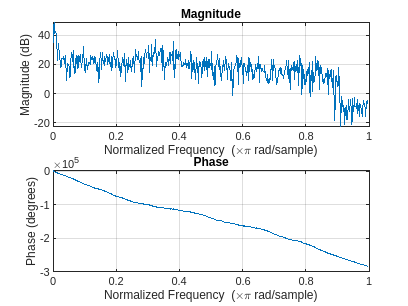

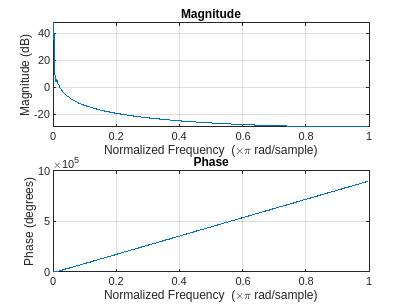

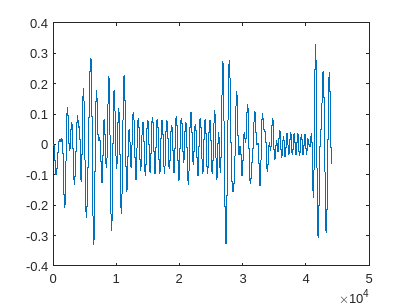

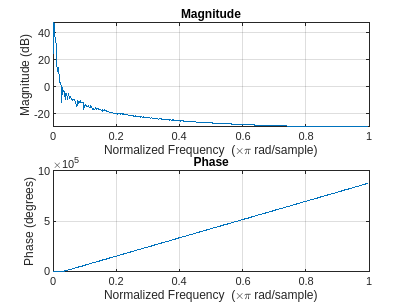

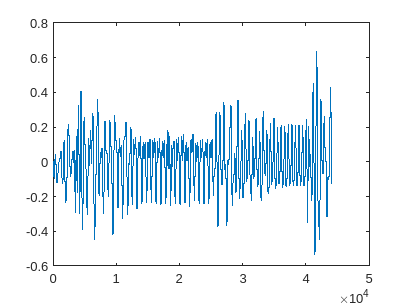

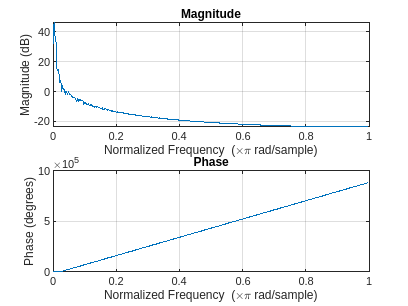

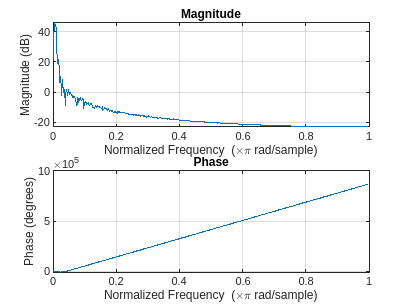

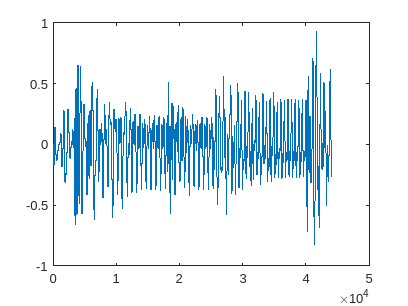

test_vec =     0.3751    0.6591    0.8003    0.8074    0.7414    0.6833    0.6934    0.7812    0.9028    0.9839    0.9594    0.8094    0.5733    0.3348    0.1856    0.1844    0.3302    0.5649    0.8007    0.9621    1.0199    1.0018    0.9748    1.0082    1.1349    1.3315    1.5259    1.6301    1.5815    1.3732    1.0591    0.7297    0.4719    0.3311    0.2936    0.2981    0.2700    0.1614   -0.0232   -0.2269   -0.3683   -0.3819   -0.2523   -0.0249    0.2123    0.3669    0.3826    0.2627    0.0649   -0.1293


out =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


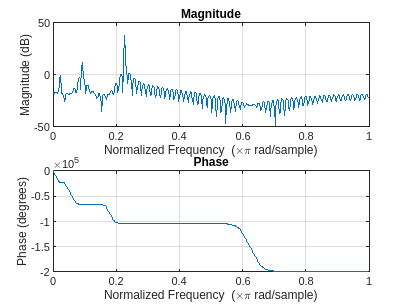

N = 2

Wn =     0.0481    0.1322


ans = 0.0608

ans = 0.1052

N = 2

Wn2 =     0.0834    0.2266


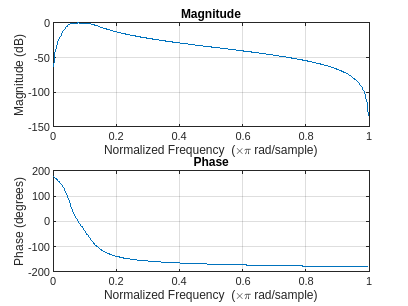

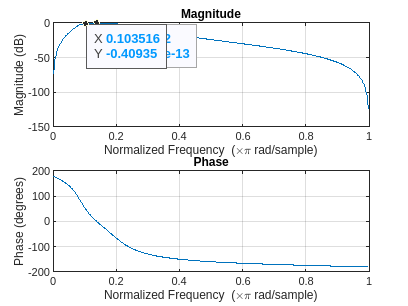

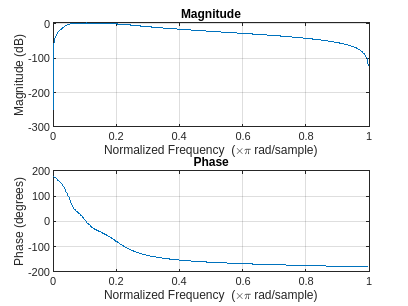

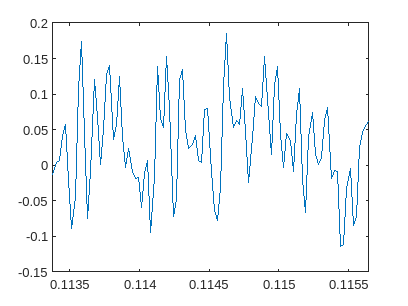



kaiserord([cut(1)  cut(2)], [1,0], [0.05, 0.01], 2)

## Echo effect

% Need to add signal filtered with an allpass filter with linear phase
test_vec = sin(50*2*pi*t_vec);
test_vec = test_vec(:);
test_vec2 = [zeros(ceil(fs/50), 1) ; test_vec(1:fs/20)];
test_vec2 = [test_vec2; zeros( length(test_vec)- length(test_vec2), 1)];
test_vec = test_vec2;

echo_time = 0.005

echo_time = 0.0050

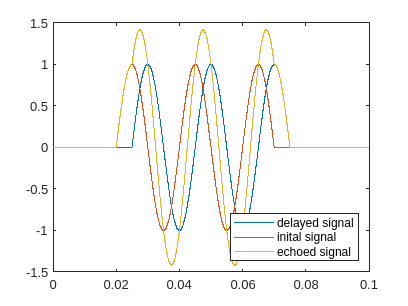

h_delay = [0; zeros(ceil(fs*echo_time)-1 , 1)];
h_delay(end) = 1;
h_delay_t = h_delay;
h_delay_t(1) = 1;

delay_sig = conv(test_vec, h_delay);
out_sig = conv(test_vec, h_delay_t);
ft_vec = 1/fs:1/fs:length(delay_sig)/fs;
figure();
plot(ft_vec, delay_sig)
hold on 
plot(t_vec, test_vec)
plot(ft_vec, out_sig)
xlim([0.0, 0.1])
legend('delayed signal', 'inital signal', 'echoed signal', 'Location','southeast')

sound(filt3, fs)